# Buck Converter Modeling and Verification in Simulink

## Modeling, simulation, and validation for control-oriented design

% Author: Luis Gaona

% Date: 2026

### 1 Overview

This Live Script documents the modeling, simulation, and verification of a DC-DC Buck converter using multiple modeling fidelities in Simulink. The focus is on establishing a validated modeling workflow suitable for both detailed time-domain analysis and control-oriented design.

The objectives of this work are:

- To implement a high-fidelity switched Buck converter model.

- To derive and simulate an averaged, control-oriented model.

- To verify the validity of the averaged representation against the switched reference model.

- To evaluate modeling trade-offs in terms of accuracy and simulation performance.

### 2. System Description

#### 2.1 Buck Converter Topology

The Buck converter consists of a controlled switch (MOSFET), a diode, an inductor, an output capacitor, and a resistive load. Energy is transferred from the input source to the load by controlling the duty cycle of the switching device. 

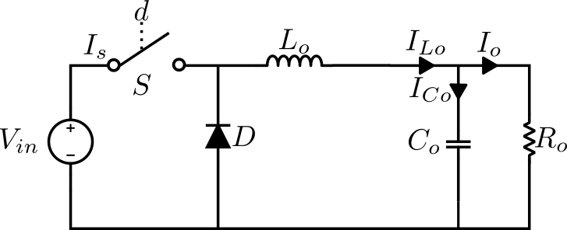

#### 2.2 Modeling Assumptions

All simulations are performed under continuous conduction mode (CCM). The converter parameters and operating point are selected to represent a typical low-voltage DC-DC conversion scenario.

- Continuous Conduction Mode (CCM)

- Ideal switch and diode

- Constant input voltage

- Negligible parasitics

- Ideal output capacitor

### 3. Mathematical Model

#### 3.1 State Variables

The system is described using the following state variables:

#### 3.2 Switched Model Equations

The switched model alternates between two linear subsystems depending on the switching state.

On state


$$\dot{i_L} = \frac{V_{in} - v_C}{L}$$



$$\dot{v_C} = \frac{i_L - \frac{v_C}{R}}{C}$$


Off state


$$\dot{i_L} = \frac{-v_C}{L}$$



$$\dot{v_C} = \frac{i_L - \frac{v_C}{R}}{C}$$


This representation captures switching ripple and high-frequency dynamics.

#### 3.3 Averaged Model

The averaged model replaces the switching behavior by its duty-cycle weighted average.


$$\dot{i_L} = \frac{DV_{in} - v_C}{L}$$



$$\dot{v_C} = \frac{i_L - \frac{v_C}{R}}{C}$$


Under steady-state CCM operation:


$$V_o = D*V_{in}$$


### 4. Simulink Implementation

#### 4.1 Switched Model

The switched model is implemented in Simulink using:

- A PWM generator operating at fixed switching frequency

- Mosfet block, diode block, series RLC branch (Capacitor, inductor, resistor)

- Fixed-step discrete solver

Model file:

thisFile = matlab.desktop.editor.getActiveFilename;
projectRoot = fileparts(thisFile);

modelsDir = fullfile(projectRoot, '..', 'models');

assert(isfolder(modelsDir), 'Models folder not found: %s', modelsDir)

open_system(fullfile(modelsDir, 'buck_switched.slx'))

#### 4.2 Averaged Model Implementation

The averaged model is implemented without explicit switching. This allows larger simulation time steps and faster execution.

Model file:

open_system(fullfile(modelsDir, 'buck_averaged.slx'))

### 5. Simulation Parameters

#### 5.1 Electrical Parameters

Vin = 28;          % Input voltage [V]
L   = 50e-6;      % Inductance [H]
C   = 500e-6;      % Capacitance [F]
R   = 3;          % Load resistance [Ohm]
D   = 0.536;         % Duty cycle
Vo = D*Vin;

fprintf('Vin = %.1f V, D = %.4f\n, Vo =%.1f\n', Vin, D, Vo)

Vin = 28.0 V, D = 0.5360
, Vo =15.0


#### 5.2 Modeling Fidelity Strategy

Two modeling fidelities are employed to address different simulation objectives.

The switched model provides a high-fidelity reference by explicitly representing switching behavior and ripple effects.

The averaged model sacrifices switching detail in exchange for improved simulation efficiency, making it suitable for control design and system-level studies.

#### 5.3 Solver Configuration

Switched model:

    Fixed-step, Ts = 1e-7 s

Averaged model:

    Fixed-step, Ts = 1e-5 s

These configurations ensure numerical stability while balancing accuracy and simulation speed.

### 6. Simulation Results

#### 6.1 Run Simulations

Run both models and collect results using To Workspace blocks.

sim_switched = sim('buck_switched.slx');
sim_averaged = sim('buck_averaged.slx');

**Switched Model Simulation**

The switched model is simulated to obtain a high-fidelity reference response capturing switching ripple and fast-scale dynamics.

**Averaged Model Simulation**

The averaged model is simulated under identical operating conditions. This model captures the dominant dynamics while eliminating switching ripple.

#### 6.2 Output Voltage Comparison

Model verification is performed by comparing key output variables from the averaged model against the switched reference.

The comparison focuses on steady-state accuracy and dynamic response consistency.

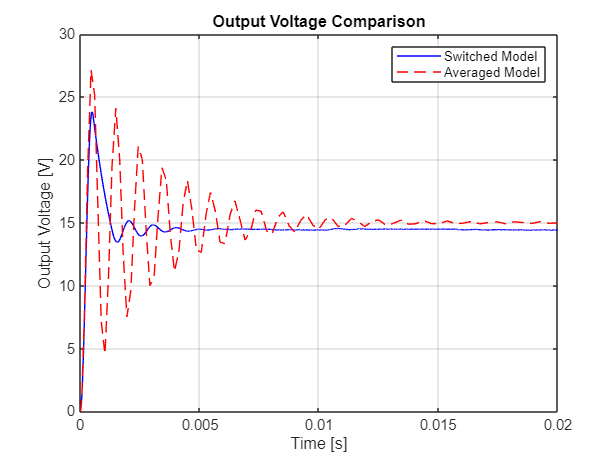

t_sw = vout_sw.time;
v_sw = vout_sw.signals.values;

t_av = vout_av.time;
v_av = vout_av.signals.values;

figure
plot(t_sw, v_sw, 'b')
hold on
plot(t_av, v_av, 'r--')
grid on
xlabel('Time [s]')
ylabel('Output Voltage [V]')
legend('Switched Model','Averaged Model')
title('Output Voltage Comparison')

hold on
plot(t_av, v_av, 'r--')
grid on
xlabel('Time [s]')
ylabel('Output Voltage [V]')
legend('Switched Model','Averaged Model')
title('Output Voltage Comparison')

#### 6.3 Inductor Current

The switched model exhibits ripple, while the averaged model represents the mean inductor current.

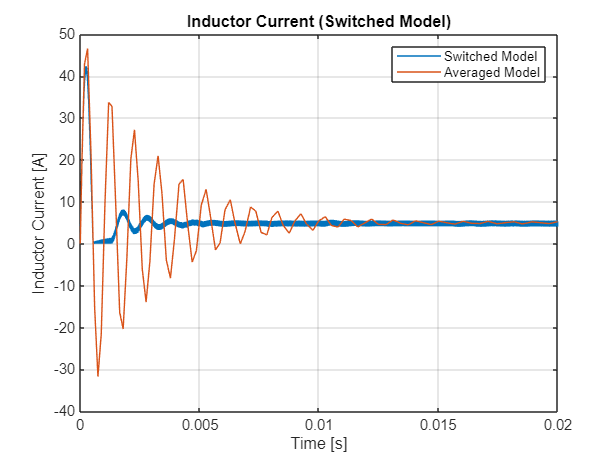

t_iL_sw = iL_sw.time;
iL_sw   = iL_sw.signals.values;

t_iL_av = iL_av.time;
iL_av   = iL_av.signals.values;

figure
plot(t_iL_sw, iL_sw)
hold on
plot(t_iL_av, iL_av)
grid on
xlabel('Time [s]')
ylabel('Inductor Current [A]')
legend('Switched Model','Averaged Model')
title('Inductor Current (Switched Model)')

### 7. Reproducibility

To reproduce these results:

- Open buck_switched.slx

- Open buck_averaged.slx

- Run this live script

- Modify duty cycle $D$ or $V_{in}$ and rerun the simulations

### 8. Limitations

- Valid only under CCM operation

- Switching losses are not modeled

- Not suitable for EMI or thermal analysis

- Averaged model does not capture ripple dynamics

### 9. Discussion of Results

The averaged model accurately reproduces the mean output voltage of the switched model, confirming the validity of the averaging assumptions under CCM operation.

As expected, high-frequency ripple present in the switched model is not captured in the averaged representation, which is acceptable for control-oriented analysis.

### 10. Conclusion

This work establishes a validated modeling hierarchy for Buck converter analysis in Simulink. The results confirm that averaged models provide an efficient and accurate representation for control design within their intended operating range, while switched models remain essential for detailed performance analysis.

### 11. References

[1] R. Erickson and D. Maksimovic, Fundamentals of Power Electronics

[2] MathWorks Documentation: DC-DC Converter Modeling